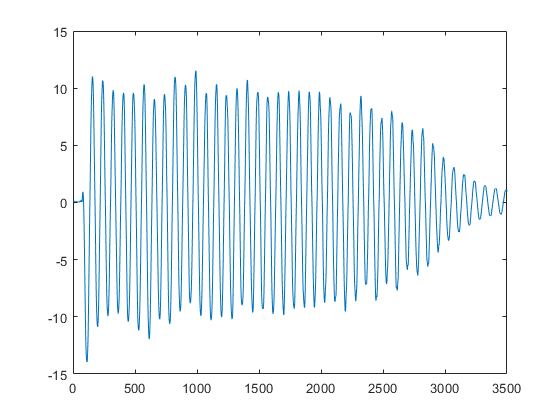

% A Novel Algorithm to Detect Broken Bars in Induction Motors
% by Mateus Ventura Souza,José Claudeni Oliveira Lima,Alexandre Magno Pinto Roque and Douglas Bressan Riffel
% Mechanical Engineering Department, Federal University of Sergipe, São Cristóvão 49100-000, SE, Brazil
% Email: dougbr @ academico.ufs.br
% Academic Editor: Antonio J. Marques Cardoso
% Machines 2021, 9(11), 250; https://doi.org/10.3390/machines9110250

% Share and cite:
% Souza, Mateus V., José C.O. Lima, Alexandre M.P. Roque, and Douglas B. Riffel 2021. "A Novel Algorithm to Detect Broken Bars in Induction Motors" Machines 9, no. 11: 250. https://doi.org/10.3390/machines9110250

load('current');

% choose the rotor
% r = 1; % Rotor without failure (HEALTHY);
% r = 2; % Rotor with one bar completely failed (1 BAR);
% r = 3; % Rotor with 2 adjacent bars totally failed (2 BAR).
% r = 4; % Rotor with 2 bars totally failed, geometrically separated by 90∘ (2 BAR 90);
r = 5; % Rotor with 2 bars totally failed, geometrically separated by 180∘ (2 BAR 180);
% r = 6; % Rotor with one bar partially broken (½ BAR);
I = Me1(:,r);

Fs = 5e3; % Signal Sampling Frequency;
Ts = 1/Fs; % Sampling period;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plot(I) % measured current in time

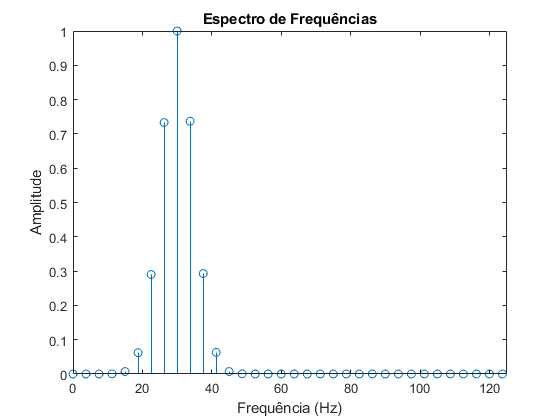

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%% Notch filter - actually, it shows not necessary anymore 
Notch = designfilt('bandstopiir','FilterOrder',20, ...
     'HalfPowerFrequency1',50,'HalfPowerFrequency2',70, ...
     'SampleRate',Fs);
I = filter(Notch,I);

%%% Normalization
I = I / 8.15; % normalized by the nominal current of the motor

f0 = 30; % central frequency of the Gaussian digital filter 

sig_min = 6/f0/6;
sigma = sig_min;
sl = 4; % how many sigmas?
l = -sl*sigma:Ts:sl*sigma;            % Size of the filter
tam_j = Fs/40; % size of the window for the command movmax
tam_l = length(l);
if 6*sigma < 3/f0
  % error('increase the sigma')
end

% Gaussian Filter
wo = 2*pi*f0;               
cst = Ts/(sigma*sqrt(2*pi));
h = cst*exp(-l.^2/(2*sigma^2));
filtro = h.*sin(wo*l);           
X=fftf(filtro,Fs);

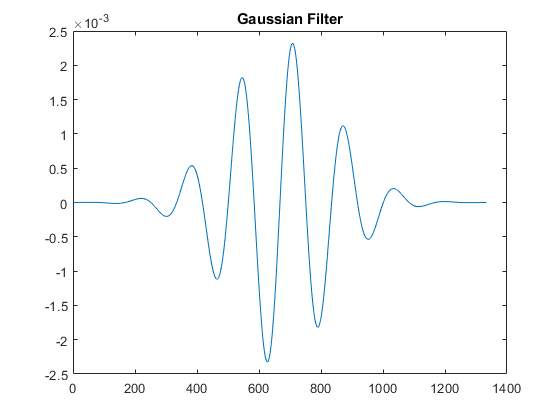

plot(filtro)
title('Gaussian Filter');

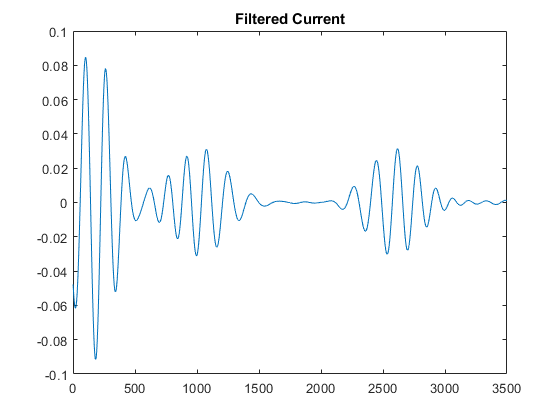



R_27 = conv(I,filtro);  
xM1 = R_27(round(length(filtro)/2):round((length(filtro)/2+length(I)-1))); % Cut the beginning and end of the convolution
plot(xM1)
title('Filtered Current');

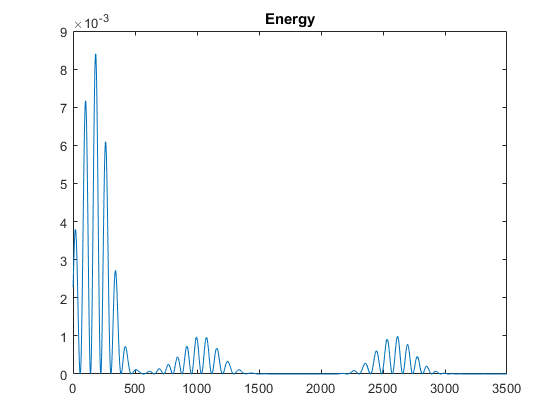



%================== Energy ===========================================
plot(xM1.^2)
title('Energy');

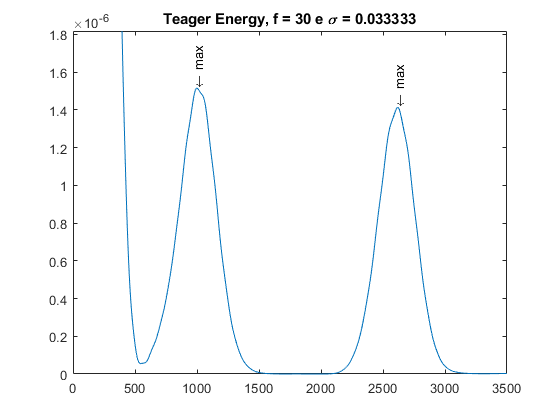

%ylim([0 4e6])

%==================Teager Energy===========================================
e1=xM1(2:end-1).^2-xM1(1:end-2).*xM1(3:end);
plot(e1)
title('Teager Energy, f = '+string(f0)+' e \sigma = '+string(sigma))

%================== Find the Maximum Values
[e_max1,t_max1]=max(e1); % this is the maximum due to the startup transient
e1_mm = movmax(e1,tam_j);
[e_max,t_max]=findpeaks(e1_mm);
if e_max(1) == e_max1
    e_max(1) = [];
    t_max(1) = [];
end
while size(e_max,1) > 2
    [a,b]=min(e_max);
    e_max(b) = [];
    t_max(b) = [];
end
t_max = t_max + tam_j/2;

t=text(t_max,e_max,'\leftarrow max');
set(t,'Rotation',90);
ylim([0 1.2*max(max(e_max))])


Delta_t = t_max(2)-t_max(1)

Delta_t = 1620

Teager_max = e_max'

Teager_max = 	1.0e+-5 *

    0.1515    0.1413
